# Custom Training Loop

## Preprocessing

inhale_data = readmatrix("res\inhale_data_v5.csv");
exhale_data = readmatrix("res\exhale_data_v5.csv");
inhale_outcome = readtable("res\inhale_outcome_v5.csv");

exhale_outcome = readtable("res\exhale_outcome_v5.csv");

inhale_verbose = readtable("res\inhale_verbose_v5.csv");
exhale_verbose = readtable("res\exhale_verbose_v5.csv");
inhale_outcome = table2array(inhale_outcome);
exhale_outcome = table2array(exhale_outcome);
inhale_verbose = table2array(inhale_verbose);
exhale_verbose = table2array(exhale_verbose);
% coeff = pca(train_data(:,1:end-1), "NumComponents", 20);
% train_data = [coeff' train_data(:,end)];

raw = [inhale_data(inhale_outcome(:,1)<=2,:);...
    exhale_data(exhale_outcome(:,1)<=2,:)];
data = cell(size(raw,1),1);
mask = cell(size(raw,1),1);
for i = 1:size(raw,1)
    tmp = reshape(raw(i,:),[],25);
    [data{i}, mask{i}] = generate_heatmap_v2(tmp(31:126,:));
    data{i} = data{i}.*mask{i};
end


% Centering/Normalization
% data = (data-mean(data,2))./std(data,[],2);

label = [categorical(inhale_outcome(inhale_outcome(:,1)<=2,1));...
    categorical(exhale_outcome(exhale_outcome(:,1)<=2,1))];
verbose = [inhale_verbose(inhale_outcome(:,1)<=2,:);...
    exhale_verbose(exhale_outcome(:,1)<=2,:)];
classes = categories(label);

c = cvpartition(label,"Holdout",0.2);

## Config Hyperparameters

numEpochs = 200;
miniBatchSize = 64;

initialLearnRate = 0.001;
decay = 0.01;
gradientDecayFactor = 0.9;
squaredGradientDecayFactor = 0.999;

## Autoencoder model

AELayers = [ ...
    imageInputLayer([size(data{1}) 1],Normalization="none")
    
    convolution2dLayer(3,8,'Stride',2,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    convolution2dLayer(3,16,'Stride',2,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    convolution2dLayer(3,32,'Stride',2,'Padding','same')
    batchNormalizationLayer
    reluLayer

    transposedConv2dLayer(3,16,'Stride',2,'Cropping','same')
    batchNormalizationLayer
    reluLayer
    
    transposedConv2dLayer(3,8,'Stride',2,'Cropping','same')
    batchNormalizationLayer
    reluLayer
    
    transposedConv2dLayer(3,1,'Stride',2,'Cropping','same')
    sigmoidLayer
    ];

## AE Training

net = dlnetwork(AELayers);

% Initialize Figure
lossFig = figure

lossFig =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


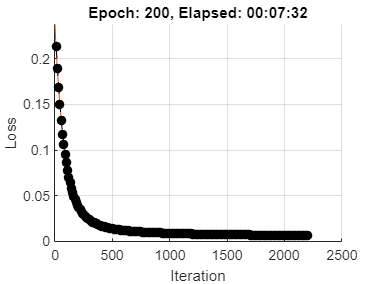

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



C = colororder;
lineLossTrain = animatedline(Color=C(2,:));
lineLossValidation = animatedline( ...
    LineStyle="--", ...
    Marker="o", ...
    MarkerFaceColor="black");
ylim([0 inf])
xlabel("Iteration")
ylabel("Loss")
grid on

trainidx = c.training;
testidx = c.test;

% Prepare minibatch
tbl = table;
tbl.data = data(trainidx);
tbl.mask = mask(trainidx);
tbl.label = label(trainidx,:);
tbl.verbose = verbose(trainidx,:);
ds = arrayDatastore(tbl,"OutputType","same");
mbq = minibatchqueue(ds, ...
    'MiniBatchSize', miniBatchSize, ...
    'MiniBatchFcn', @preprocessMiniBatch, ...
    'MiniBatchFormat', {'SSCB','SSCB','',''});

tbl = table;
tbl.data = data(testidx);
tbl.mask = mask(testidx);
tbl.label = label(testidx,:);
tbl.verbose = verbose(testidx,:);
ds = arrayDatastore(tbl,"OutputType","same");
mbqValidation = minibatchqueue(ds, ...
    'MiniBatchSize', length(tbl.label), ...
    'MiniBatchFcn', @preprocessMiniBatch, ...
    'MiniBatchFormat', {'SSCB','SSCB','',''});

trailingAvg = [];
trailingAvgSq = [];

best_loss = 1e5;
best_net = net;

iteration = 0;
start = tic;

% Loop over epochs.
for epoch = 1:numEpochs
    disp(epoch)

    % Shuffle data.
    shuffle(mbq);
    
    % Loop over mini-batches.
    while hasdata(mbq)
        iteration = iteration + 1;
        
        % Read mini-batch of data.
        [X,M,T] = next(mbq);
        
        % Evaluate the model gradients, state, and loss using dlfeval and the
        % modelLoss function and update the network state.
        [loss,gradients,state] = dlfeval(@modelLoss,net,X,M,T);
        net.State = state;
        
        % Determine learning rate for time-based decay learning rate schedule.
%         learnRate = initialLearnRate/(1 + decay*iteration);
        learnRate = initialLearnRate;

        % Update the network parameters using the Adam optimizer.
        [net,trailingAvg,trailingAvgSq] = adamupdate(net, gradients, ...
            trailingAvg, trailingAvgSq, iteration, learnRate, ...
            gradientDecayFactor, squaredGradientDecayFactor);
        
        % Display the training progress.
        figure(lossFig)
        D = duration(0,0,toc(start),Format="hh:mm:ss");
        loss = double(loss);
        addpoints(lineLossTrain,iteration,loss)
        title("Epoch: " + epoch + ", Elapsed: " + string(D))
%         drawnow
    end

    % Validation
    reset(mbqValidation);

    [X,M,T] = next(mbqValidation);
%     X_prep = X .* (rand(size(X)) > 0.2);
    Y = predict(net,X);
%     lossValidation = mse(Y,X);
    lossValidation = mean((Y-X).^2,'all');
    
    % Update plot.
    figure(lossFig)
    lossValidation = double(lossValidation);
    addpoints(lineLossValidation,iteration,lossValidation)
%     drawnow

    if lossValidation < best_loss
        best_loss = lossValidation;
        best_net = net;
    end  
end

## Assemble encoder

encoderLayers = [ ...
    imageInputLayer([size(data{1}) 1],Normalization="none")
    
    convolution2dLayer(3,8,'Stride',2,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    convolution2dLayer(3,16,'Stride',2,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    convolution2dLayer(3,32,'Stride',2,'Padding','same')
    batchNormalizationLayer
    reluLayer];

encoder = dlnetwork(encoderLayers);
encoder.Learnables = best_net.Learnables(1:12,:);
save("encoder_heatmap_v5.mat","encoder");

## Model Loss Function

function [loss,gradients,state] = modelLoss(net,X,M,T)


% Random zeroing
% X_prep = X;
% X_prep = X .* (rand(size(X)) > 0.3);
X_prep = X + 0.2 * randn(size(X)) .* M;
        
% Forward data through network.
[Y,state] = forward(net,X_prep);

% Calculate cross-entropy loss.]
% loss = mse(Y,X);
loss = mean((Y-X).^2,'all');

% Calculate gradients of loss with respect to learnable parameters.
gradients = dlgradient(loss,net.Learnables);

end

## Mini Batch Preprocessing Function

function [X,M,T,V] = preprocessMiniBatch(dataX,dataM,dataT,dataV)

X = cat(4,dataX{1:end});
M = cat(4,dataM{1:end});

T = cat(1,dataT{1:end});
T = onehotencode(T,2);
T = T';

V = cat(1,dataV{1:end});

end